% Problem 0

load('Homework2.mat')

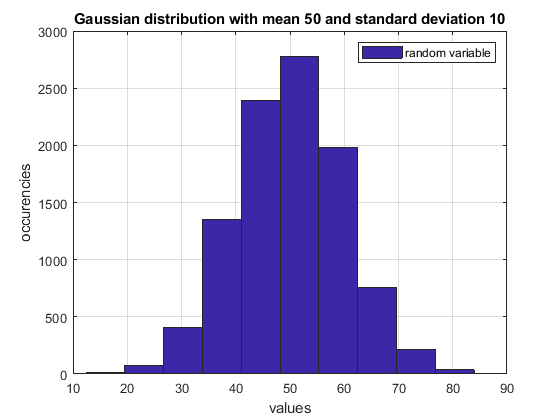

% Problem 1

% Get a sample from Gaussian Distribution with mean 50 and standard
% deviation 10.

r = 50 + 10.*randn(10000,1);
figure;
hist(r);
grid; legend('random variable');
title("Gaussian distribution with mean 50 and standard deviation 10");
xlabel('values')
ylabel('occurencies')

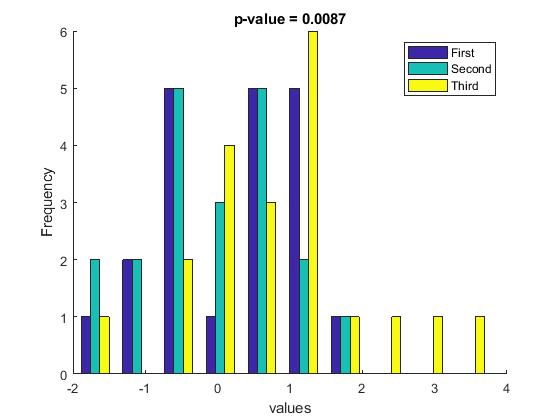

% Problem 2

% So, we have data1 variable. It contains array 3x20. Each row represents
% distinct group data. Our aim is to test null hypothesis that all three
% samples came from the same distribution

% For that we use randomization. 10 000 simulation. Then we calculate
% p-value.

% But first we use the analytical  approach.
% For that we calculate mean for each group. Then calculate deviation
% between means for these three groups. If the variabilityy is significantly
% high, then we claim these groups are diffirent


group_mean = mean(data1,2);
av_std = std(group_mean);


% Flatten the data
alldata = data1(:);

% Preallocate array for the average deviation for each step in
% randomization
results = zeros(1,10000);

for num=1:10000
    % Reshuffle the data randomly
    randomized_data = alldata(randperm(length(alldata)));
    
    % Reshape data in [3x20] array
    reshaped = reshape(randomized_data, [3 20]);
    
    % Calculate statistic for a randomized group
    iter_av_std = std(mean(reshaped,2));
    
    % Store metric for Nth iteration
    results(num) = iter_av_std;
end


% Calculate p-value to assest whether deviation is significant or not

p  = sum(results> av_std) / length(results);


% Visualize the data
figure;cla;hold on;
hist(data1')
title(sprintf("p-value = %g",p));
legend('First','Second','Third');
xlabel('values')
ylabel('Frequency')

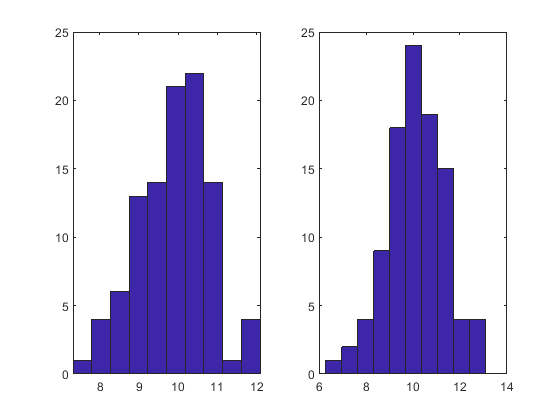

%  Problem 4

% Visualize data
figure;
subplot(1,2,1)
hist(data2a)
subplot(1,2,2)
hist(data2b)


%Qualtify the difference
delta = data2b - data2a

delta =     0.4719   -0.0522   -0.6941    1.0416    1.2821   -0.1256    0.0584    2.5050   -0.0239    0.0907    0.1474   -0.2619    1.9768   -0.2673    1.2681   -1.1847   -0.0783   -0.4410    1.3939    0.1684    1.0373    1.6542    1.3086    0.7302    1.0254   -1.5412   -0.4849    0.4444    0.1159    0.4891    0.3647   -1.1931    0.3905    1.1333   -0.3780   -0.6242   -0.8446    0.5622    1.6905   -0.9840   -0.0410    0.7716    0.6752   -0.6662   -0.4826   -0.4844   -0.2688    0.6770    0.3406   -0.1429


% Calculate actually observed difference
actualval = mean(delta);

%  the null hypothesis is that the values in x  come from a probability
%  distribution that has a mean of 0. (in other words, the experimental
%  manipulation doesn't really increase or decrease the measured values.)

% Let's use the observed x values as an empirical probability distribution
% that conforms to the null hypothesis. However, we first need to substract
% off the mean of x.
xcentered = delta - mean(delta);

% Also visualize substracted data
figure; hold on;
h = plot([ delta' xcentered'])

h =   2×1 Line array:

  Line
  Line


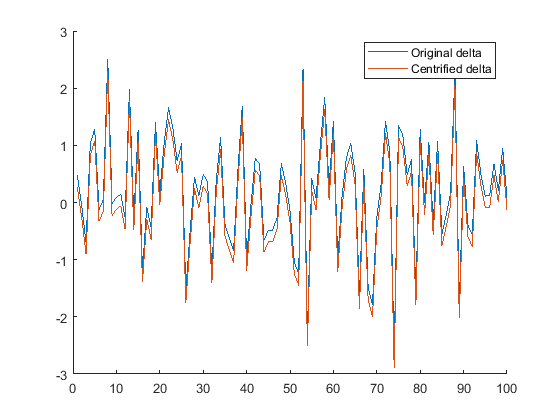

legend(h,"Original delta", "Centrified delta")


results = zeros(1,10000);

% Seems to be equal to randomization method. 
% //TODO: What is the difference?
for num=1:10000
    
    % vector of indices (each element is a random integer between
    % 1 and n where n is the number of data points)
    
    % an array of indexes to take for each bootstrap sample
    ix = ceil(length(xcentered)* rand(1, length(xcentered)));
    
    % Randomly chosen elements from the original sample
    x_i = xcentered(ix);
    
    results(num) = mean(x_i);
    
end

% Calculate amount of observation that showed to exceed the original means
% and become extreme values.
% Calculate two tailed p-value

pval = sum(abs(results)> abs(actualval)) / length(results);

disp(sprintf("Two-tailed p-value is %g",pval));

Two-tailed p-value is 0.0368


% Problem 4

% Coin flipping simulation code has been taken from 
% https://www.mathworks.com/matlabcentral/answers/393131-how-to-simulate-a-coin-flip-experiment-and-count-the-number-of-changeovers

N_attempts = [10 100 1000];
numtimes = 10000;


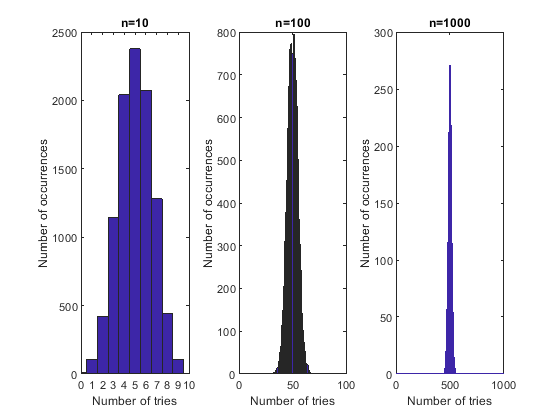

% Or try to be more compact, as it was suggested in already solved homework
% exercise

% MUCH FASTER.
% DONT ITERATE OVER LARGE DATA

figure;

% Iterate over three subplot
for k=1:length(N_attempts)
    % Take a new number of times
    N = N_attempts(k);
   
    
    % Make 10 000 iterations for the taken N size
    attempts = round(rand(10000, N));
    
    loc_results = sum(attempts==0,2);
    
    % Register a new subplot
    subplot(1,length(N_attempts),k);
    
    % Plot histogram for N-th size
    hist(loc_results, 0:1:N);
    
    title(sprintf("n=%g",N));
    xlabel("Number of tries");
    ylabel("Number of occurrences")
    
    % Make sure the axis' bounds are set correctly
    % e.g. for N = 10 => [0 10]
    %      for N = 100 => [0 100]
    ax = axis;
    axis([0 N ax(3:4)])
end